# Visualization of graph data

## Small graph data

set(0,'DefaultFigureWindowStyle','docked')
addpath("functions")

pathNodes = "data\small_graph_nodes.txt";
pathEdges = "data\small_graph_edges.txt";
[nodes,~,n] = merg(pathNodes,pathEdges);
[M,~,Cos,Sin,emb1,emb2] = build(pathNodes,pathEdges);


building M...
Elapsed time is 0.000335 seconds.

building P...
Elapsed time is 0.000173 seconds.


The sparsity patterns for the Sin and Cos matrices.

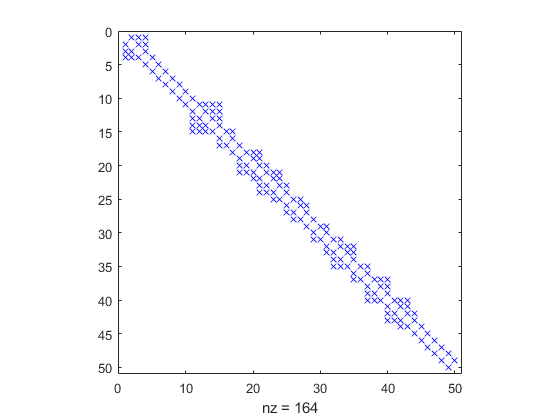

spy(Cos,'xb');

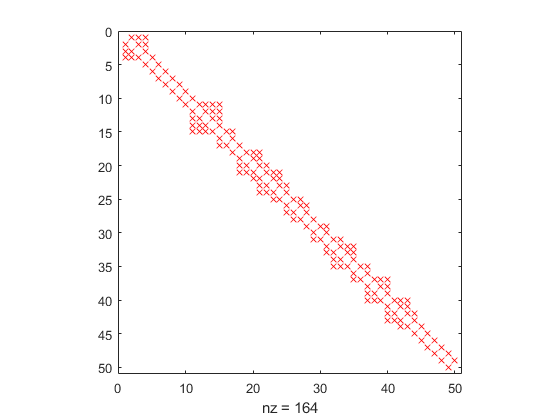

spy(Sin,'xr');

The head of the M matrix. Its pattern should be falling diagonals with verticals at each iteration.

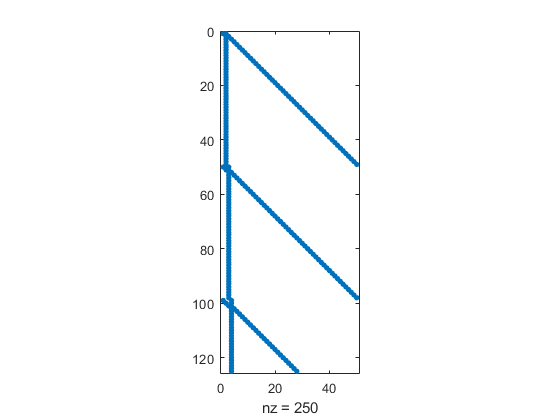

spy(headN(M,ceil(2.5*n)));

Before we go on plotting, we created a function *(see addpoints)* to plot some points over a color gradient to keep track of the location of some specific points. Through this we get a better grasp of the embeddings' changes. *(See *[https://de.mathworks.com/help/matlab/ref/uisetcolor.html](https://de.mathworks.com/help/matlab/ref/uisetcolor.html)*)*

% uisetcolor for the colors
col1 = [1, 0, 0];
col2 = [0, 1, 0];

Plot now the actual graph that is given. **Cos** does function as the adjacency matrix here. For the real adjacency matrix get the nonzeros from Cos. If no adjacency is given we can take only the vertices without interconnections. *(See section ****large graph****)*

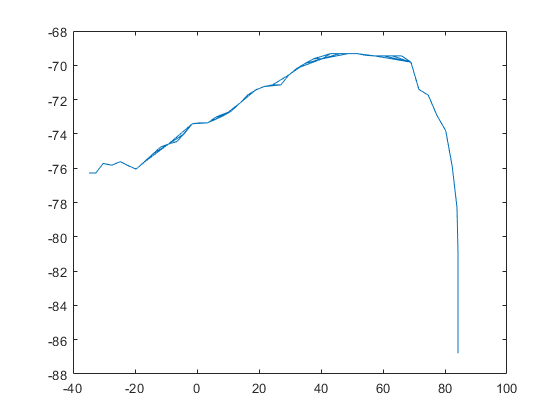

gplot(Cos,nodes(:,2:3))

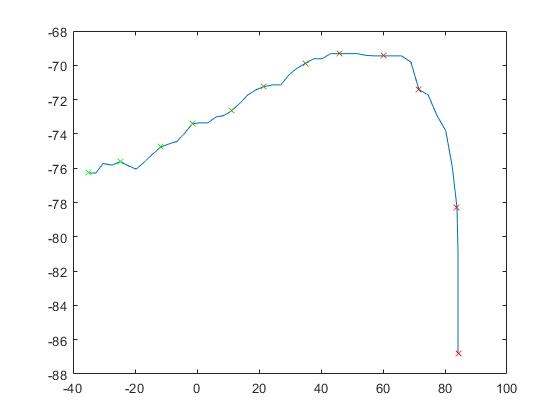

% the following two lines were rendered unnecessary due to
% plotcolorgradient()
% plot(nodes(:,2),nodes(:,3),".")
% addpoints(n/4,col1,col2,nodes(:,2:3))
plotcolorgradient(n/4,col1,col2,nodes(:,2:3),true,true)

Display the first embedding solution. This embedding was calculated by improper usage of **inv()**.

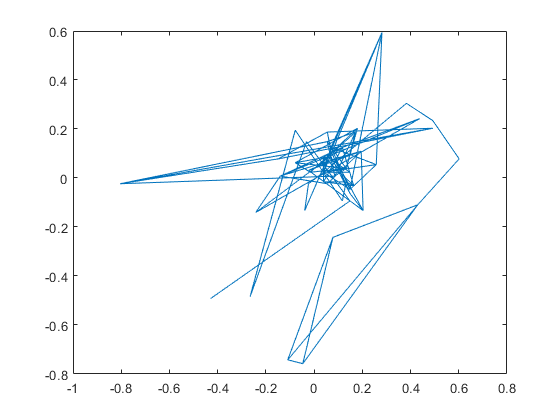

gplot(Cos,emb1)

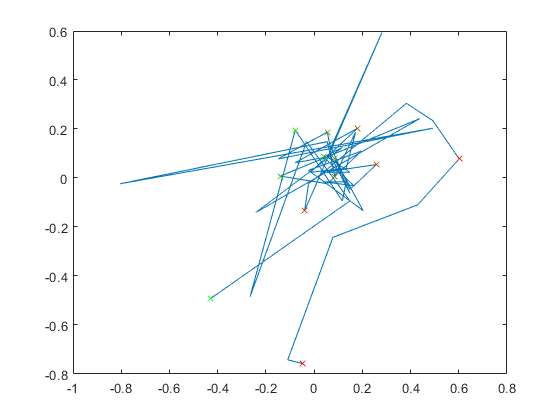

plotcolorgradient(n/4,col1,col2,emb1,true,true)

Display the second embedding solution. This embedding was calculated by the proper way of **A\b**. Here **b** was a matrix as well. *(See ****building.mlx****)*

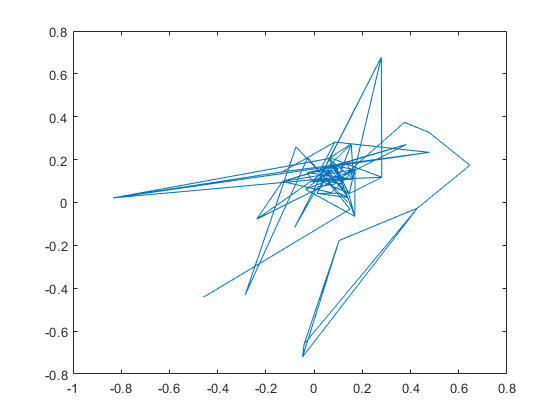

gplot(Cos,emb2)

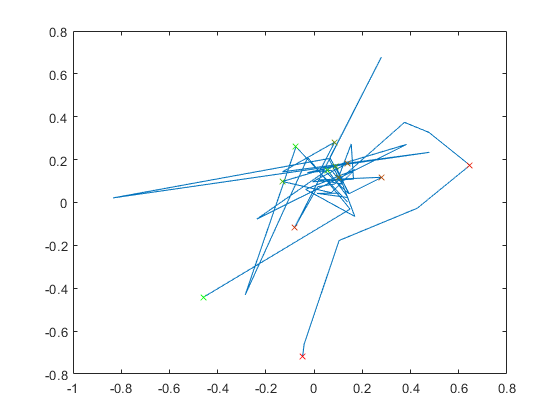

% plot(emb2(:,1),emb2(:,2),".")
plotcolorgradient(n/4,col1,col2,emb2,true,true)

On this last graph there is visible some circular structure. This is interesting in a way that it differs the first version of the improper usage of **inv()** a lot. This might be interesting for understanding the desired solution of embeddings and worth discussing more.

## Clustering

Let us try **clustering **with **dbscan() **and **kmeans()**.

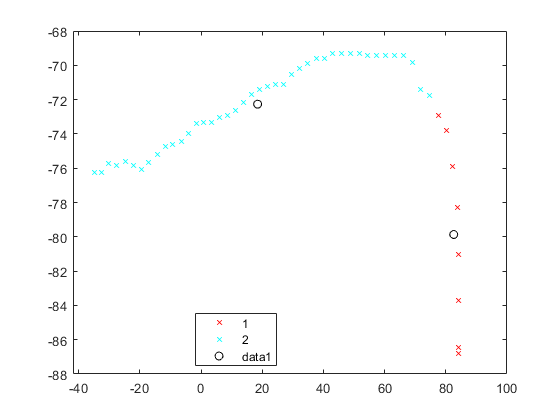

plotCluster(nodes,6,5,'on',false,"db");

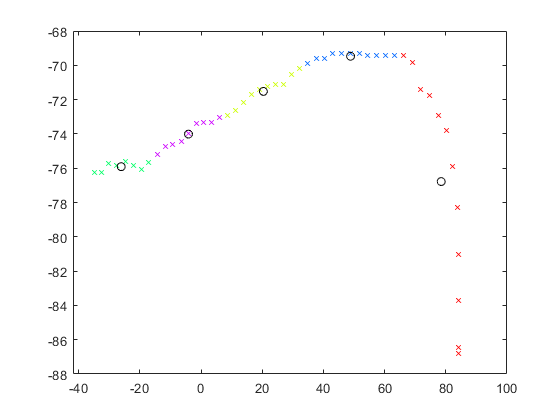

plotCluster(nodes,1.2,5,'off',false,"km");

## Large graph data

Here we want to use the **large data set** Tristan gave us instead of the partial one above. Due to the large number of nodes and edges we cannot calculate an adjacency matrix. This would break the limit of data storage as it demands **9.4GB**. As for now we just display the nodes without interconnecting edges.

% this was executed on 3rd January 11:11 AM
% pathNodes = "data\large_graph_nodes.txt";
% pathEdges = "data\large_graph_edges.txt";
% [nodes,~,n] = merg(pathNodes,pathEdges);
% [M,~,Cos,Sin,emb1,emb2] = build(pathNodes,pathEdges);
load materials\large_graph_data_merged.mat

The sparsity patterns for the Sin and Cos matrices.

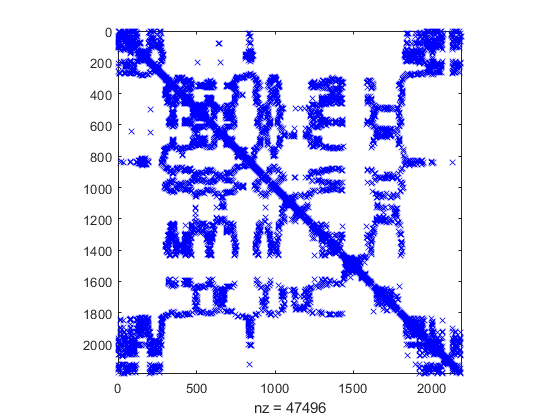

spy(Cos,'xb');

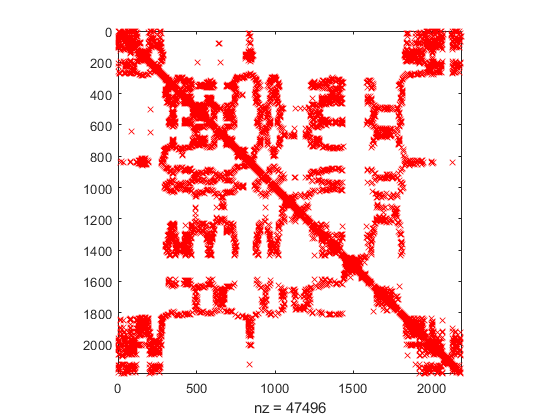

spy(Sin,'xr');

The head of the M matrix. Its pattern should be falling diagonals with verticals at each iteration.

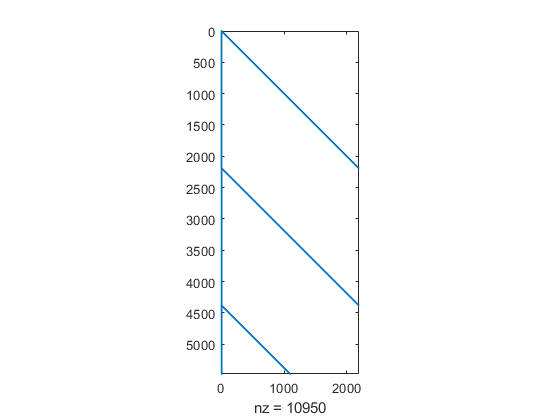

spy(headN(M,ceil(2.5*n)));

Plot here the actual graph that is given. **Cos** does function as the adjacency matrix here. For the real adjacency matrix get the nonzeros from Cos. If no adjacency is given we can take only the vertices without interconnections. *(See section ****large graph****)*

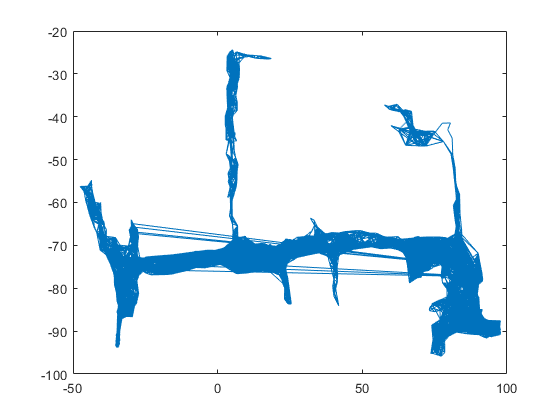

gplot(Cos,nodes(:,2:3))

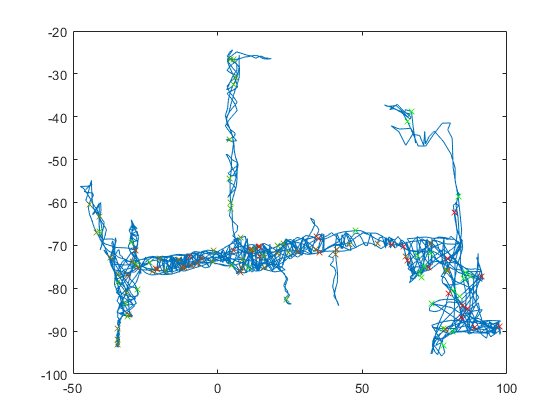

% plot(nodes(:,2),nodes(:,3),".")
plotcolorgradient(n/20,col1,col2,nodes(:,2:3),true,true)

Display the first embedding solution. This embedding was calculated by improper usage of **inv()**.

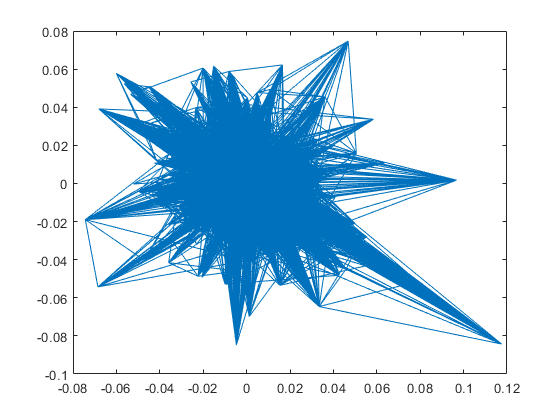

gplot(Cos,emb1)

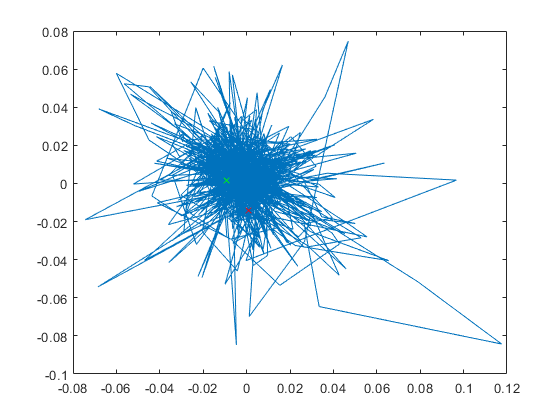

% plot(emb1(:,1),emb1(:,2),".")
plotcolorgradient(2,col1,col2,emb1,true,true)

Display the second embedding solution. This embedding was calculated by the proper way of **A\b**. Here **b** was a matrix as well. *(See ****building.mlx****)*

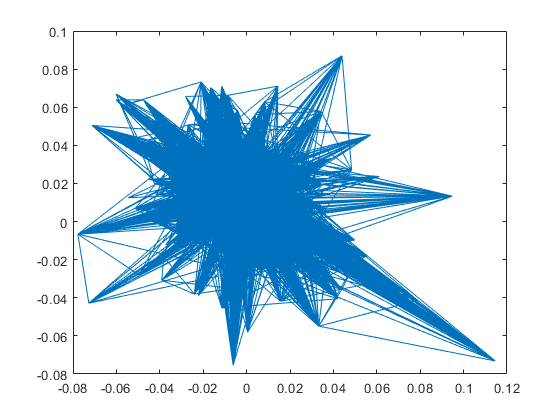

gplot(Cos,emb2)

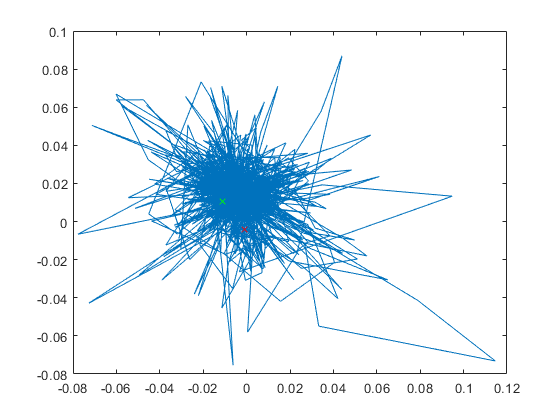

% plot(emb2(:,1),emb2(:,2),".")
plotcolorgradient(2,col1,col2,emb2,true,true)

On this last graph there is visible some circular structure. This is interesting in a way that it differs the first version of the improper usage of **inv()** a lot. This might be interesting for understanding the desired solution of embeddings and worth discussing more.

## Clustering

Let's again cluster, this time the large graph. It is a bit more interesting than the small graph.

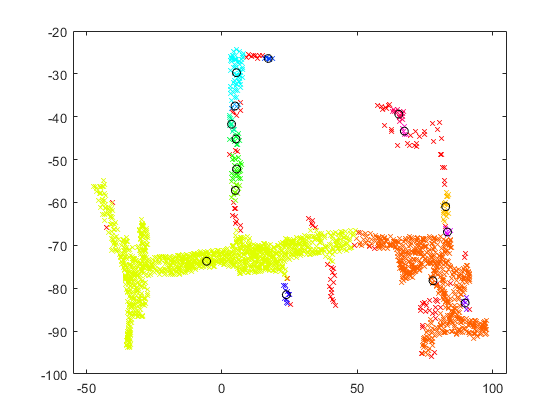

plotCluster(nodes,1.5,5,'off',false,"db");

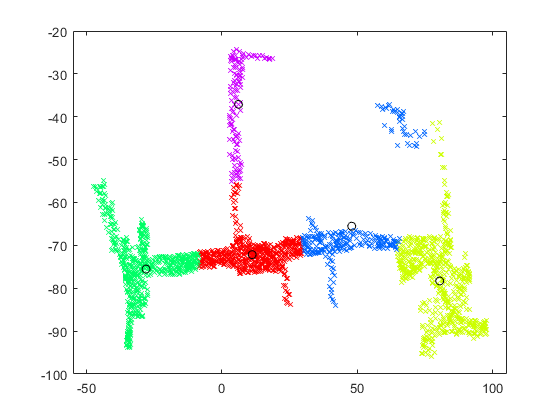

plotCluster(nodes,1.2,5,'off',false,"km");

## Aftermath

% this was executed on 3rd January 11:11 AM
% clc
% clearvars -except edges nodes n M P Cos Sin emb1 emb2
% save materials\large_graph_data_merged.mat